# Linear Control Design 2 - Fall 2018 - Exam Part I - Solution Manual

## Introduction

The Part I of the Exam in Linear Control Design 2 (E18) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**The scoring of each problem is clearly stated.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E18'

Exam = 'LCD2 E18'

Student_Name = 'Student Name'

Student_Name = 'Student Name'

Student_Number = 'Student Number'

Student_Number = 'Student Number'

## Output feedback control of a mixing tank

A mixing tank is a dynamical system where a liquid with temperature $T_k$ and volume flow $Q_k$ is mixed with another liquid with temperature $T_v$ and volume flow $Q_v$. It is assumed that the mixed liquid is stirred so that its temperature $T_u$ is approximately the same everywhere in the tank. The temperature of the released liquid at the outlet is $T_u$ (the same as in the tank) and the volume flow is $Q_u$. The outlet valve has a constant but adjustable area setting $A_v$.  The two volume flows $Q_k$ and $Q_v$ are determined by individual control valves which receive the input voltages $U_1$ and $U_2$. The level $H$ of the mixed flow in the tank and the temperature $T_u$ are measured with transducers whose outputs are the voltages $Y_1$ and $Y_2$. The following figure shows a schematic of the mixing tank.

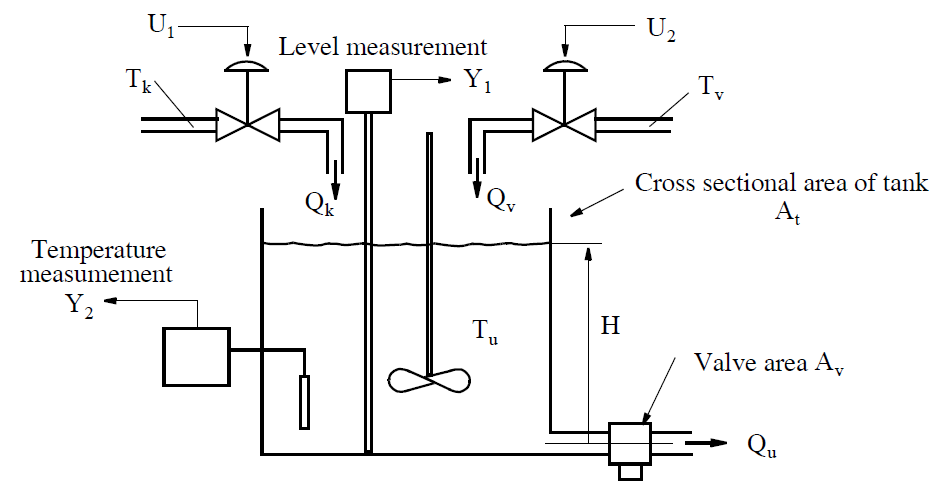

**System Dynamics**

The nonlinear dynamics of the mixing tank is described by the following equations:

- Conservation of mass/volume: $A_t\frac{dH}{dt} = Q_k+Q_v-Q_u$, where $A_t$ is the cross-sectional area of the tank

- Conservation of energy: $A_t\rho c\frac{d}{dt}(T_uH) = \rho c (Q_kT_k + Q_vT_v - Q_uT_u)$, where $\rho$ is the mass density and $c$ is the specific heat capacity of the liquid.

- Flow equation for both control valves: $Q = C_v U$, where $C_v$ is the valve flow coefficient

- Temperature measurement: $Y_1 = k_tT_u$, where $k_t$ is the transducing constant

- Level measurement: $Y_2 = k_hH$, where $k_h$ is the transducing constant

Let the state vector be $\mathbf{x} = [H,T_u]^T$ and the output vector be $\mathbf{y} = [Y_1,Y_2]^T$. Then the nonlinear state space representation of the system is


$$\dot{x}_1 = \frac{1}{A_t}\left(C_v\left(U_1 + U_2\right)-k_v A_v \sqrt{H}\right)$$



$$\dot{x}_2 = \frac{C_v}{A_t H}\left(\left(T_k - T_u\right)U_1 + \left(T_v - T_u\right)U_2\right)$$



$$y_1 = k_tT_u$$



$$y_2 = k_hH$$


The nonlinear model is implemented in the Simulink file MixingTank_NonlinearModel_SimulinkYYYYC, where YYYYC refers to the Simulink version (2017b, 2017a, 2016b, etc.). The numerical values for the model parameters are provided right below.

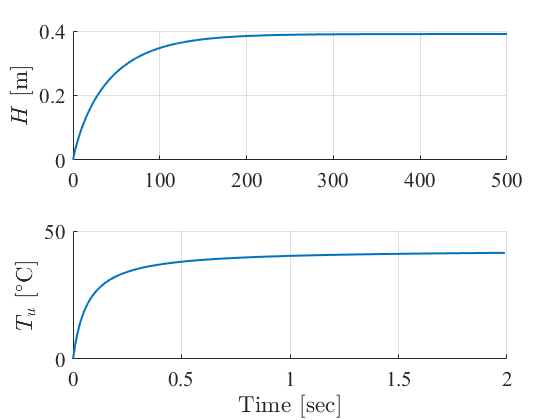

% Simulator parameters (RG)
SIM_TIME = 500; % simulation time (can be changed as needed)
STEP_SIZE = 0.01; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'MixingTank_NonlinearModel_Simulink2017b';

% Model paramters (RG)
% System parameters
At = 0.2; % tank cross-sectional area [m^2]
kv = 0.004; % valve flow coefficient [m^(5/2)/sec]
Av = 1.2; % valve area (dimensionless parameter)
Cv = 0.0005; % valve flow coefficient [m^3/(sec*V)]
kt = 0.1; % transducer constant [0.1 V/degC]
kh = 5; % transducer constant [V/m]
Tk = 25; % temperature [deg]
Tv = 60; % temperature [deg]

% Test the provided nonlinear model (RG)
time = (0:STEP_SIZE:SIM_TIME)';
x0 = [0.001,0]; % initial condition x0 = [H,Tu]'. The initial condition for H is different 
% from zero because in the second differential equation we divide by H and a zero initial 
% condition will give rise to an infinite rate of change.
U10 = 3; % input voltage valve 1 [V]
U20 = 3; % input voltage valve 2 [V]
U = [U10 U20].*ones(length(time),1); % controllable inputs
D = [Tk Tv Av].*ones(length(time),1); % disturbances
sim(SIMULINK_FILENAME,SIM_TIME,[],[time U D])

% Plot temporal behaviour of the state of the nonlinear model (RG)
H = logsout.getElement(1).Values.Data;
Tu = logsout.getElement(2).Values.Data;

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,H,'LineWidth',1.5)
ylabel('$H$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time(1:200),Tu(1:200),'LineWidth',1.5)
ylabel('$T_u$ [$^\circ$C]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

## Operating point and linearization

**Problem 1 [2 points] **Numerically determine the operating point $\mathbf{u}_0$ of the valves $U_1$ and $U_2$ associated with the stationary state $\mathbf{x}_0=[0.8,38]^T$ and while keeping the disturbances constant at their nominal values, i.e. $\mathbf{d}_0=[T_k,Tv,Av]^T = [25,60,1.2]^T$.  Linearize the system around the operatig point $(\mathbf{x}_0,\mathbf{u}_0,\mathbf{d}_0)$.

% The steady state value of the input u0 is found by using the function trim
x0 = [0.8,38]';
d0 = [25,60,1.2]';
y0 = [kt*x0(2) kh*x0(1)]';
[xss,uss,yss,dx]=trim(SIMULINK_FILENAME,x0,[3,3,d0']',y0,[1;2],[3;4;5],[1;2])

xss =     0.8000
   38.0000


uss =     5.3972
    3.1893
   25.0000
   60.0000
    1.2000


yss =     3.8000
    4.0000


dx = 	1.0e+-12 *

    0.0138
    0.2976


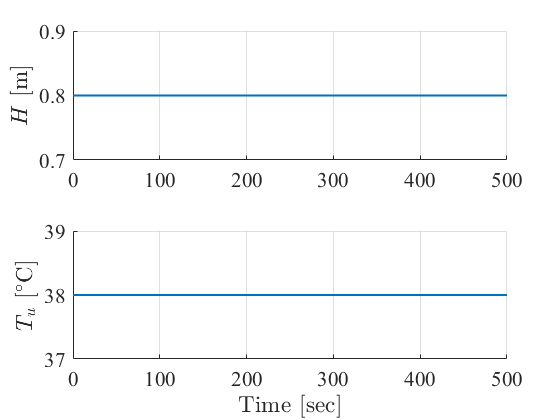


x0 = xss;
u0 = uss(1:2);
d0 = uss(3:5);

% The stationary condition is verified through a simulation of the nonlinear system
U = [time ones(length(time),length(uss)).*uss'];
sim(SIMULINK_FILENAME,SIM_TIME,[],U)

% Plot temporal behaviour of the state of the nonlinear model
H = logsout.getElement(1).Values.Data;
Tu = logsout.getElement(2).Values.Data;

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,H,'LineWidth',1.5)
ylabel('$H$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
ylim([0.7 0.9]);
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,Tu,'LineWidth',1.5)
ylabel('$T_u$ [$^\circ$C]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')


% Linearization of the system is performed using linmod
[Aol,Bol,Col,Dol] = linmod(SIMULINK_FILENAME,x0,[u0',d0']');
Bv = Bol(:,3:5); % disturbance input matrix
Bol = Bol(:,1:2);
Dol = Dol(:,1:2);
sys_ol = ss(Aol,Bol,Col,Dol)


sys_ol =
 
  A = 
              x1         x2
   x1   -0.01342          0
   x2  -3.72e-13   -0.02683
 
  B = 
             u1        u2
   x1    0.0025    0.0025
   x2  -0.04062   0.06875
 
  C = 
        x1   x2
   y1    0  0.1
   y2    5    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



## Stability analysis

**Problem 2 [2 points]** Assess the internal and external stability of the linear system.

% The internal stability is assessed by checking the position of the 
% eigenvalues in the complex plane. The external stability is evaluated 
% looking at tht position of the poles.

lambda_ol = eig(Aol); % open loop eignevalues
disp('The open loop eignevalues are')

The open loop eignevalues are


disp(lambda_ol)

   -0.0268
   -0.0134



disp(['Since the real part of the both eigenvalues is negative then the system' ...
    ' is asymptotically stable'])

Since the real part of the both eigenvalues is negative then the system is asymptotically stable



[numG,denG] = ss2tf(sys_ol.a,sys_ol.b,sys_ol.c,sys_ol.d,1);
p_ol = roots(denG); % open loop poles
disp('The open loop poles are')

The open loop poles are


disp(p_ol)

   -0.0268
   -0.0134



disp(['Since the real part of the both poles is negative then the system' ...
    ' is BIBO stable'])

Since the real part of the both poles is negative then the system is BIBO stable


## Control system design for regulation of level and temperature

The main control objective is to regulate the level $H$ and the temperature $T_u$ of the mixed liquid at the desired set-points despite the action of the disturbances $T_k, T_v$ and $A_v$.

Closed-loop system requirements

1) The steady state error for both outputs must be zero in relation to step changes of the set-points and/or the disturbances.

2) For step changes of $\pm20\%$ of the nominal value of $A_v$ the controller regulates the fluid level $H$ with

        a) a maximum overshoot/downshoot in the range 3% - 5%  

        b) a settling time between 50 and 100 seconds

**Problem 3 [6 points]** Under the assumption that the state is fully accessible design a discrete time controller that meets the aforementioned specifications on the nonlinear system using the eigenstructure assignment method. Validate your design through simulation on the linear and nonlinear model.

% To meet the first closed-loop requirement the control architecture must include 
% an integral action for both state variables. Since the controller must be designed 
% in discrete time a proper sampling time need to be identified. The desired settling 
% time is then used to determine a suitable Ts.

min_sett_time = 50; % [sec]
Ts = min_sett_time/10

Ts = 5

tau_ol = 1./abs(lambda_ol); % open loop time constants
disp('The open loop time constants are')

The open loop time constants are


disp(tau_ol)

   37.2678
   74.5356



% The smallest open loop time constant is less than 10 times larger than the computed 
% sampling time. If we take this into consideration then we could reduce the sampling 
% time to 4 seconds. We verify the suitability of the chosen sampling time by comparing 
% the step response of the discretized system with that one of the continuous time system

sys_ol_dt = c2d(sys_ol,Ts)


sys_ol_dt =
 
  A = 
               x1          x2
   x1      0.9351           0
   x2  -1.682e-12      0.8744
 
  B = 
            u1       u2
   x1  0.01209  0.01209
   x2  -0.1901   0.3217
 
  C = 
        x1   x2
   y1    0  0.1
   y2    5    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: 5 seconds
Discrete-time state-space model.



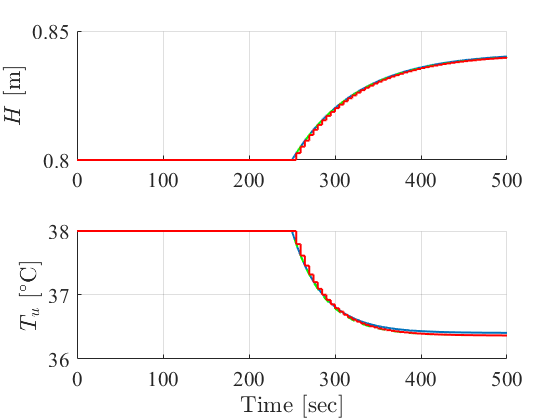

[~,Gv] = c2d(Aol,Bv,Ts); % discretization of disturbance input matrix

U = [[u0(1) u0(2)].*ones((length(time)-1)/2,1);[1.1*u0(1) 0.9*u0(2)].*ones((length(time)-1)/2+1,1)]; % controllable inputs
D = [d0(1) d0(2) d0(3)].*ones(length(time),1); % disturbances
sim(SIMULINK_FILENAME,SIM_TIME,[],[time U D])

% Plot temporal behaviour of the state of the nonlinear model
H = logsout.getElement(1).Values.Data;
Tu = logsout.getElement(2).Values.Data;

% Simulation of continuous time linearized system
U_ct = U-[u0(1) u0(2)];
[y_ct,t_ct,x_ct] = lsim(sys_ol,U_ct,time);

% Simulation of discrete time linearized system
U_dt = U(1:500:end,:)-[u0(1) u0(2)]; % sampled input
[y_dt,t_dt,x_dt] = lsim(sys_ol_dt,U_dt);

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,H,time,x_ct(:,1)+x0(1),'--g','LineWidth',1.5)
stairs(t_dt,x_dt(:,1)+x0(1),'r','LineWidth',1.5)
ylabel('$H$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,Tu,time,x_ct(:,2)+x0(2),'--g','LineWidth',1.5)
stairs(t_dt,x_dt(:,2)+x0(2),'r','LineWidth',1.5)
ylabel('$T_u$ [$^\circ$C]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')


% The simulation shows that the discretized linear model accurately follows 
% the continous time linear model. Both models have the same mismatch with 
% respect to the nonlinear model. Therefore we can conclude that the chosen sampling 
% time suffices to properly evaluate the dynamics of open loop system.

% Full state feedback with integral action
F = sys_ol_dt.a;
G = sys_ol_dt.b;
% Compute the reachability matrix and check if the system is reachable
Mr = ctrb(F,G);
if rank(Mr) == size(F,1)
    disp('The open loop system is reachable')
end

The open loop system is reachable



Fi = [F zeros(size(F,1),2);-Ts*Col eye(size(Col,1),2)];
Gi = [G;zeros(size(Col,1),2)];
Gr = [zeros(2);Ts*[kt 0;0 kh]]; % reference input matrix (assume that the reference is 
% in degrees Celsius and meters)
Gvi = [Gv;zeros(size(Col,1),3)];
Ci = [Col,zeros(size(Col,1),2)];

% From closed-loop requirement 2 we derive the region of the complex plane where the
% eigenvalues should be placed.

sett_time_des = 90; % desired settling time [sec]
tau_cl = sett_time_des/4; % closed-loop time constant 

dr_des = 0.7; % desired damping ratio

% To fulfill the requirement 2 we assign a complex pair alpha +/- j*beta. Alpha determines 
% the decay rate of the envelope of the oscillatory motion when the system is initialized 
% with a non-zero initial condition. Beta is related to the damping

alpha1 = -1/tau_cl;
beta1 = abs(alpha1)*sqrt((1-dr_des^2)/dr_des^2);
tau2 = 20;
dr_des2 = 0.55;
alpha2 = -1/tau2;
beta2 = abs(alpha2)*sqrt((1-dr_des2^2)/dr_des2^2);
lambda_cl_des = [alpha1+1i*beta1,alpha1-1i*beta1,alpha2+1i*beta2,alpha2-1i*beta2];
lambda_cl_des_dt = exp(lambda_cl_des.*Ts)

lambda_cl_des_dt =    0.7802 + 0.1800i   0.7802 - 0.1800i   0.7234 + 0.2886i   0.7234 - 0.2886i



K = place(Fi,Gi,lambda_cl_des_dt)

K =    17.4744   -0.7689    0.5316   -0.1121
   14.4355    0.8406   -0.6313   -0.1806


Kfs = K(:,1:2);
Ki = -K(:,3:4);

sys_cl_dt = ss(Fi-Gi*K,[Gr Gvi],Ci,[],Ts);
lambda_cl_dt = eig(sys_cl_dt)

lambda_cl_dt =    0.7802 + 0.1800i
   0.7802 - 0.1800i
   0.7234 + 0.2886i
   0.7234 - 0.2886i



% Design validation on the linear model
SIMULINK_FILENAME = 'MixingTank_IntegralControl_Simulink2017b';
R = [x0(2) x0(1)].*ones(length(time),1); % references
D = [[d0(1) d0(2) d0(3)].*ones((length(time)-1)/4,1);...
    [d0(1) d0(2) 1.2*d0(3)].*ones((length(time)-1)/4,1);...
    [d0(1) d0(2) d0(3)].*ones((length(time)-1)/4,1);...
    [d0(1) d0(2) 0.8*d0(3)].*ones((length(time)-1)/4+1,1)]; % disturbances
xi0 = zeros(2,1); % initial condition for the controller integrators
sim(SIMULINK_FILENAME,SIM_TIME,[],[time R D])

% Plot temporal behaviour of the state of the nonlinear model
u_fs = -logsout.getElement(1).Values.Data;
u_i = logsout.getElement(2).Values.Data;
timeDT = logsout.getElement(1).Values.Time;
H = logsout.getElement(3).Values.Data;
Tu = logsout.getElement(4).Values.Data;
u = logsout.getElement(5).Values.Data;

% Simulation of discrete time closed-loop linearized system
U = [R D];
U_dt = U(1:500:end,:)-[x0(2) x0(1) d0(1) d0(2) d0(3)]; % sampled input
[y_dt,t_dt,x_dt] = lsim(sys_cl_dt,U_dt);

bound_3pct = x0(1)*[0.97 1.03];
bound_5pct = x0(1)*[0.95 1.05];
settling_p1pct = x0(1)*1.01;
settling_m1pct = x0(1)*0.99;
downshoot = 100*(x0(1) - min(H))/x0(1);
overshoot = 100*(max(H) - x0(1))/x0(1);
disp('The overshootshoot is')

The overshootshoot is


disp(strcat(num2str(overshoot),'%'))

4.666%


disp('The downhootshoot is')

The downhootshoot is


disp(strcat(num2str(downshoot),'%'))

4.4906%


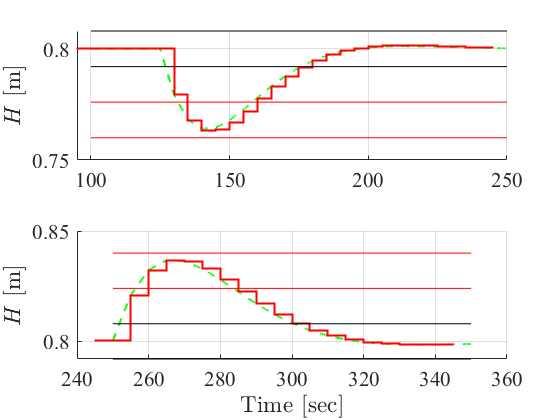


figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time(100/STEP_SIZE:250/STEP_SIZE),H(100/STEP_SIZE:250/STEP_SIZE),'--g','LineWidth',1.5)
stairs(t_dt(100/Ts:250/Ts),x_dt(100/Ts:250/Ts,1)+x0(1),'r','LineWidth',1.5)
line([time(100/STEP_SIZE) time(250/STEP_SIZE)],[bound_3pct(1) bound_3pct(1)],'Color','r')
line([time(100/STEP_SIZE) time(250/STEP_SIZE)],[bound_5pct(1) bound_5pct(1)],'Color','r')
line([time(100/STEP_SIZE) time(250/STEP_SIZE)],[settling_p1pct settling_p1pct],'Color','k')
line([time(100/STEP_SIZE) time(250/STEP_SIZE)],[settling_m1pct settling_m1pct],'Color','k')
ylabel('$H$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time(250/STEP_SIZE:350/STEP_SIZE),H(250/STEP_SIZE:350/STEP_SIZE),'--g','LineWidth',1.5)
stairs(t_dt(250/Ts:350/Ts),x_dt(250/Ts:350/Ts,1)+x0(1),'r','LineWidth',1.5)
line([time(250/STEP_SIZE) time(350/STEP_SIZE)],[bound_3pct(2) bound_3pct(2)],'Color','r')
line([time(250/STEP_SIZE) time(350/STEP_SIZE)],[bound_5pct(2) bound_5pct(2)],'Color','r')
line([time(250/STEP_SIZE) time(350/STEP_SIZE)],[settling_p1pct settling_p1pct],'Color','k')
line([time(250/STEP_SIZE) time(350/STEP_SIZE)],[settling_m1pct settling_m1pct],'Color','k')
ylabel('$H$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
% plot(time,Tu,'--g','LineWidth',1.5)
% stairs(t_dt,x_dt(:,2)+x0(2),'r','LineWidth',1.5)
% ylabel('$T_u$ [$^\circ$C]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

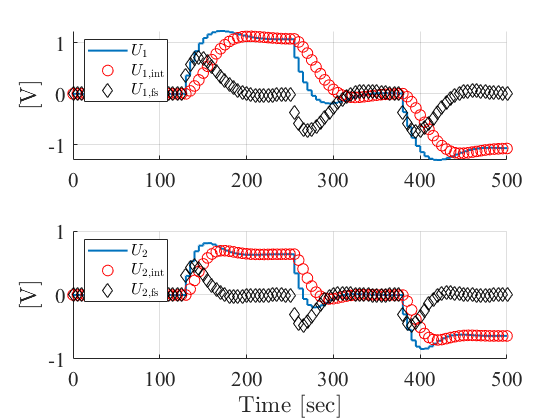


figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
stairs(timeDT,u(:,1)-u0(1),'LineWidth',1.5)
plot(timeDT,u_i(:,1),'or',timeDT,u_fs(:,1),'dk','MarkerSize',8)
ylabel('[V]','FontName','times','FontSize',16,'Interpreter','latex')
leg1 = legend('$U_1$','$U_{1,\mathrm{int}}$','$U_{1,\mathrm{fs}}$','Location','NorthWest');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
stairs(timeDT,u(:,2)-u0(2),'LineWidth',1.5)
plot(timeDT,u_i(:,2),'or',timeDT,u_fs(:,2),'dk','MarkerSize',8)
ylabel('[V]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
leg2 = legend('$U_2$','$U_{2,\mathrm{int}}$','$U_{2,\mathrm{fs}}$','Location','NorthWest');
set(leg2,'FontName','times','FontSize',12,'Interpreter','latex')

## Observer design for estimation of the valve area $A_v$

To determine the unknown valve area $A_v$ determining the output flow $Q_u$ and thereby affecting the liquid level $H$, a state estimator in the form of a Kalman filter can be employed.

The two measured outputs are affected by uncorrelated white noise sources $[v_t,v_h]^T$ with zero mean and maximum amplitudes of $\pm 0.05$volts, i.e.


$$y_1 = k_tT_u + v_t \\
y_2 = k_hH + v_h$$


**Problem 4 [4 points]** Under the assumption that the valve area $A_v$ is constant, design a discrete time Kalman filter able to reconstruct the state vector and the unknown valve area. 

% Model for Kalman filter design including estimation of the disturbance
F_kf = [F, Gv(:,3);zeros(1,2) 1];
G_kf = [G;zeros(1,2)];
C_kf = [Col zeros(2,1)];
% It is assumed that process noise acts on all state variables of the system. 
% The continuous time noise input matrix Bv is now defined under the assumption 
% that the noise enters the system in the feedack loops of the open loop system
% Bv_kf = diag([Aol(1,1) Aol(2,2) 1]);
Bv_kf = diag([1 1 1]);
sigma_H = 1;
sigma_Tu = 0.5;
sigma_Av = 5;
V1 = diag([sigma_H^2 sigma_Tu^2 sigma_Av^2]); % Process noise intensity
meas_noise_max_Ampl = 0.05;
sigma_y1 = meas_noise_max_Ampl/3;
sigma_y2 = meas_noise_max_Ampl/3;
V2 = diag([sigma_y1^2 sigma_y2^2]); % Measurement noise intensity
% Process noise discretization
V1d = Bv_kf*V1*Bv_kf'*Ts;
Gv_kf = eye(3);
V2d = V2/Ts;

% Check observability
Mo = obsv(F_kf,C_kf);
if rank(Mo) == size(F_kf,1)
    disp('The open loop system is observable')
end

The open loop system is observable



% Design of the discrete time closed form Kalman filter
[L_kf,P,Qe_th,lambda_kf_dt] = dlqe(F_kf,Gv_kf,C_kf,V1d,V2d)

L_kf =    -0.0000    0.2000
    9.9559   -0.0000
    0.0000   -0.8068


P =     7.6805   -0.0000  -30.9848
   -0.0000    1.2542    0.0000
  -30.9848    0.0000  483.1696


Qe_th =     0.0000   -0.0000   -0.0000
   -0.0000    0.0055    0.0000
   -0.0000    0.0000  358.1696


lambda_kf_dt =     0.0000
    0.6510
    0.0039


**Problem 5 [4 points] **Assess the estimation performance of the Kalman filter when tested on the open loop nonlinear system for step changes of $\pm20\%$ of the nominal value of $A_v$.

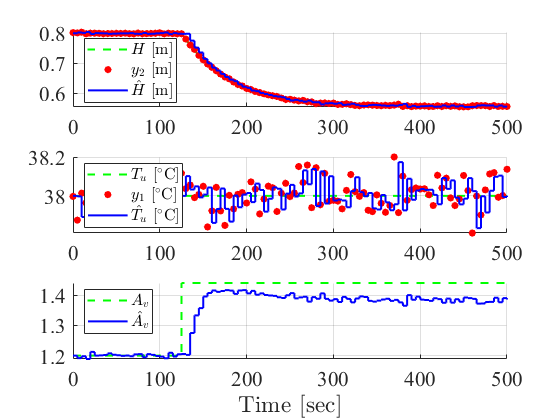

% Your solution goes here

% Design validation on the linear model
SIMULINK_FILENAME = 'MixingTank_KalmanFilter_Simulink2017b';
D = [[d0(1) d0(2) d0(3)].*ones((length(time)-1)/4,1);...
    [d0(1) d0(2) 1.2*d0(3)].*ones(3*(length(time)-1)/4+1,1)]; % disturbances
x0hat = zeros(3,1); % initial condition for the Kalman filter
sim(SIMULINK_FILENAME,SIM_TIME,[],[time D])

% Plot temporal behaviour of the state of the nonlinear model
xhat = logsout.getElement(1).Values.Data;
yhat = logsout.getElement(2).Values.Data;
timeDT = logsout.getElement(1).Values.Time;
H = logsout.getElement(3).Values.Data;
Tu = logsout.getElement(4).Values.Data;
y1 = 1/kt*logsout.getElement(7).Values.Data; % measurement 1 expressed in deg Celsius
y2 = 1/kh*logsout.getElement(6).Values.Data; % measurement 1 expressed in meters

figure, h1 = subplot(3,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,H,'--g',timeDT,y2,'or','MarkerSize',4,'MarkerFaceColor','r','LineWidth',1.5)
stairs(timeDT,xhat(:,1),'b','LineWidth',1.5)
leg1 = legend('$H$ [m]','$y_2$ [m]','$\hat{H}$ [m]','Location','NorthWest');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')

h2 = subplot(3,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,Tu,'--g',timeDT,y1,'or','MarkerSize',4,'MarkerFaceColor','r','LineWidth',1.5)
stairs(timeDT,xhat(:,2),'b','LineWidth',1.5)
leg2 = legend('$T_u$ [$^\circ$C]','$y_1$ [$^\circ$C]','$\hat{T_u}$ [$^\circ$C]','Location','NorthWest');
set(leg2,'FontName','times','FontSize',12,'Interpreter','latex')

h3 = subplot(3,1,3); set(h3,'FontName','times','FontSize',16)
hold on, grid on
plot(time,D(:,3),'--g','LineWidth',1.5)
stairs(timeDT,xhat(:,3),'b','LineWidth',1.5)
leg3 = legend('$A_v$','$\hat{A_v}$','Location','NorthWest');
set(leg3,'FontName','times','FontSize',12,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

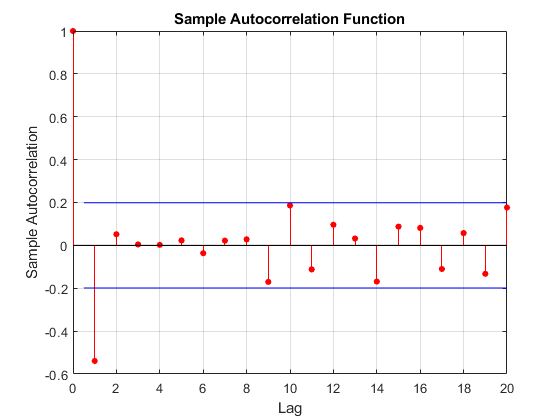


% Kalman filter performance analysis in stationary conditions
SIMULINK_FILENAME = 'MixingTank_KalmanFilter_Simulink2017b';
D = [[d0(1) d0(2) d0(3)].*ones((length(time)),1)]; % disturbances
x0hat = zeros(3,1); % initial condition for the Kalman filter
sim(SIMULINK_FILENAME,SIM_TIME,[],[time D])

% Plot temporal behaviour of the state of the nonlinear model
xhat = logsout.getElement(1).Values.Data;
yhat = logsout.getElement(2).Values.Data;
timeDT = logsout.getElement(1).Values.Time;
H = logsout.getElement(3).Values.Data;
Tu = logsout.getElement(4).Values.Data;
y1 = logsout.getElement(7).Values.Data; % measurement 1 expressed in deg Celsius
y2 = logsout.getElement(6).Values.Data; % measurement 1 expressed in meters

inno = [y1 y2] - yhat; % innovation process

figure, autocorr(inno(:,1))

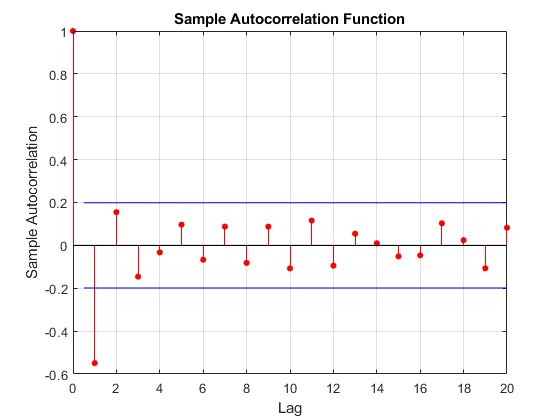

figure, autocorr(inno(:,2))


x = [H(1:Ts/STEP_SIZE:end) Tu(1:Ts/STEP_SIZE:end) D(1:Ts/STEP_SIZE:end,3)];
est_err = x - xhat;
Qe_sim = cov(est_err)

Qe_sim =     0.0000   -0.0000   -0.0000
   -0.0000    0.0043    0.0000
   -0.0000    0.0000    0.0000


disp('Qe_th =')

Qe_th =


disp(Qe_th) 

    0.0000   -0.0000   -0.0000
   -0.0000    0.0055    0.0000
   -0.0000    0.0000  358.1696

